% Initialization & reset.
clear;
setup;                          % Make sure we can find NEURON.
n = neuron.start_session();     % Initialize the NEURON session.

NEURON -- VERSION 9.0.dev-1329-g4b26ff135+ HEAD (4b26ff135+) 2023-03-30
Duke, Yale, and the BlueBrain Project -- Copyright 1984-2022
See http://neuron.yale.edu/neuron/credits



n.reset_sections();             % Reset topology.

% Make axon.
axon = n.Section("axon");       % Construct a Section.
axon.set_diameter(20);          % Set the Section diameter.
axon.insert_mechanism("hh");    % Insert a mechanism.

% Add current clamp.
iclamp = n.IClamp(axon, 0);     % Insert current clamp at start of axon.
iclamp.del = 0.5;               % Set delay (ms).
iclamp.dur = 1;                 % Set duration (ms).

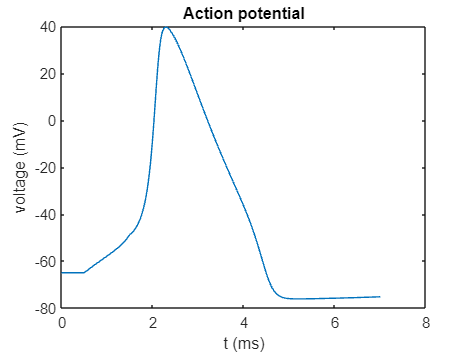

% Set parameters.
initial_membrane_potential = -65; % mV
simulation_time =              7; % ms
current_clamp_strength =      1; % nA

% Action potential figure.
[t_vec, v_vec] = get_action_potential(n, axon, iclamp, ...
                                      initial_membrane_potential, ...
                                      simulation_time, ...
                                      current_clamp_strength);
plot(t_vec, v_vec);
title("Action potential");
xlabel("t (ms)");
ylabel("voltage (mV)");

function [t_vec, v_vec] = get_action_potential(n, axon, iclamp, ...
    init_pot, sim_time, I_amp)
    
    % Track time with Vector t_vec.
    t_vec = n.Vector();             % Construct a Vector.
    t = n.ref("t");                 % Create a reference to t.
    t_vec.record(t);                % Record t with the Vector t_vec.
    
    % Track voltage at two points.
    v_vec = n.Vector();             % Construct a Vector.
    v = axon.ref("v", 1);           % Create a reference (v1) to the voltage.
                                    % at the end of the axon.
    v_vec.record(v);                % Record v1 with the Vector v1_vec.

    % Set IClamp properties.
    iclamp.amp = I_amp;             % Set current amplitude (nA).

    % Run simulation.
    n.finitialize(init_pot);        % Set initial membrane potential (mV).
    while n.t < sim_time            % Iterate up to sim_time (ms).
        n.fadvance();               % Advance the time by n.dt.
    end

    t_vec = t_vec.double();
    v_vec = v_vec.double();
end